R = 2.0;                % Ohms
L = 0.5;                % Henrys
Km = 0.1;               % torque constant
Kb = 0.1;               % back emf constant
Kf = 0.2;               % Nms
J = 0.02;               % kg.m^2/s^2


s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



H_arm = Km/(L*s + R)

H_arm =
 
     0.1
  ---------
  0.5 s + 2
 
Continuous-time transfer function.



H_load = 1/(J*s + Kf)

H_load =
 
       1
  ------------
  0.02 s + 0.2
 
Continuous-time transfer function.



dcm_ol = H_load*H_arm

dcm_ol =
 
            0.1
  -----------------------
  0.01 s^2 + 0.14 s + 0.4
 
Continuous-time transfer function.



dcm_cl = feedback(dcm_ol,Kb,1,1)

dcm_cl =
 
            0.1
  ------------------------
  0.01 s^2 + 0.14 s + 0.41
 
Continuous-time transfer function.



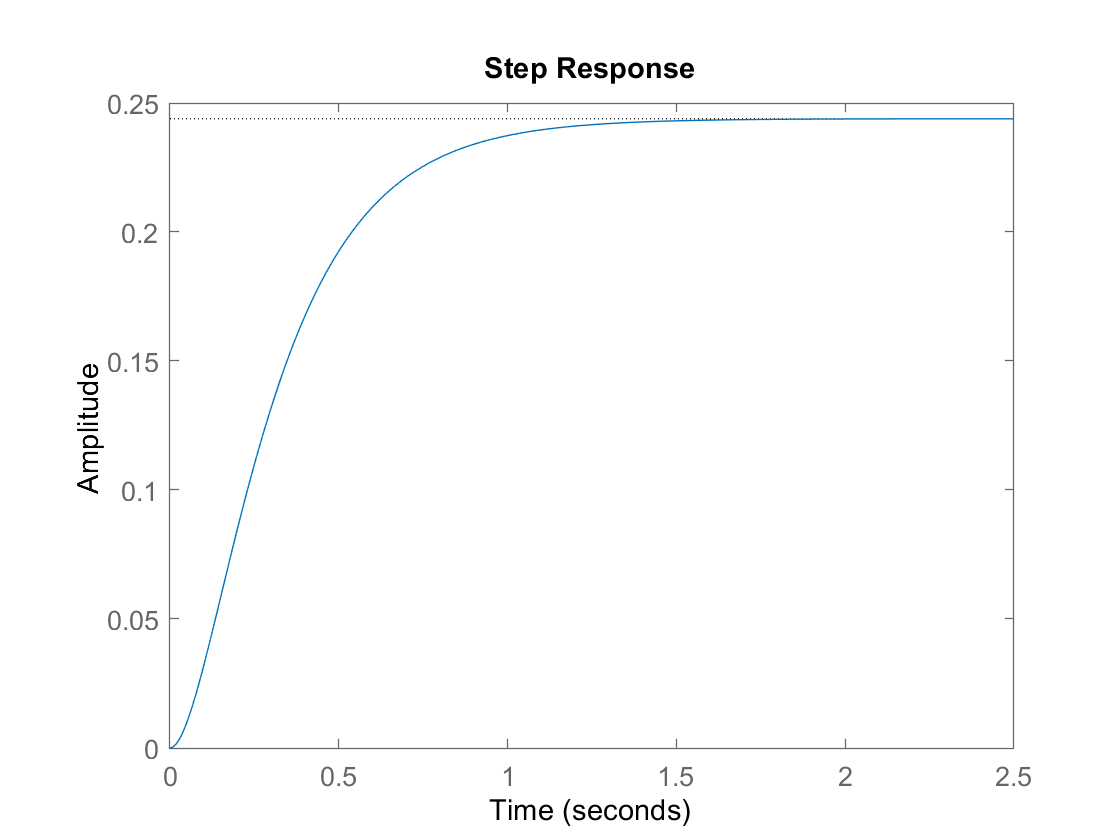

step(dcm_cl)